% SHAPC-Mean and SHAPC-Var
alg = "der";
dataset = "cifar10";
avg_all = true;

save_path = sprintf("%s/%s/shapc_vals.mat", alg, dataset);
shapc_struct = load(save_path);
num_samples = 1000;
num_sessions = 5;

if avg_all
    % Load SHAPC values all
    shapc_avgs = [];
    for i=1:num_sessions-1
        for j=i:num_sessions-1
            pair_str = 'sc' + string(i-1) +string(j);
            shapcs = [];
            for k=1:length(fieldnames(shapc_struct.(pair_str)))
                sample_str = 'sample' + string(k-1);
                shapcs = [shapcs; shapc_struct.(pair_str).(sample_str)];
            end
            shapc_avgs = [shapc_avgs; mean(shapcs)];
    
        end
    end
end

% Note the shapc is represented as percentage
disp("From averaging all tasks together:")

From averaging all tasks together:


shapc_mean_perc = mean(shapc_avgs)

shapc_mean_perc = single
40.2768

shapc_mean = mean(shapc_avgs) / 100

shapc_mean = single
0.4028

Y = [shapc_mean_perc];

save_path = sprintf("%s/%s/shapc_vals_first_last.mat", alg, dataset);
shapc_struct = load(save_path);
% Load SHAPC values (First and Last Only)
shapc_avgs = [];
for i=1:num_sessions-1
    for j=4
        pair_str = 'sc' + string(i-1) +string(j);
        shapcs = [];
        sample_list = string(fieldnames(shapc_struct.(pair_str)));
        for k=1:length(fieldnames(shapc_struct.(pair_str)))
            sample_str = sample_list(k);%'sample' + string(k-1);
            shapcs = [shapcs; shapc_struct.(pair_str).(sample_str)];
        end
        shapc_avgs = [shapc_avgs; mean(shapcs)];

    end
end

% Note the shapc is represented as percentage
disp("From averaging only the first and last tasks together:")

From averaging only the first and last tasks together:


shapc_mean_perc = mean(shapc_avgs)

shapc_mean_perc = single
41.9342

shapc_mean = mean(shapc_avgs) / 100

shapc_mean = single
0.4193

Y = [Y shapc_mean_perc];

% Plot the results
bar(Y)
std_dev = std(Y)

std_dev = single
1.1719

abs_diff = abs(Y(1)-Y(2))

abs_diff = single
1.6574

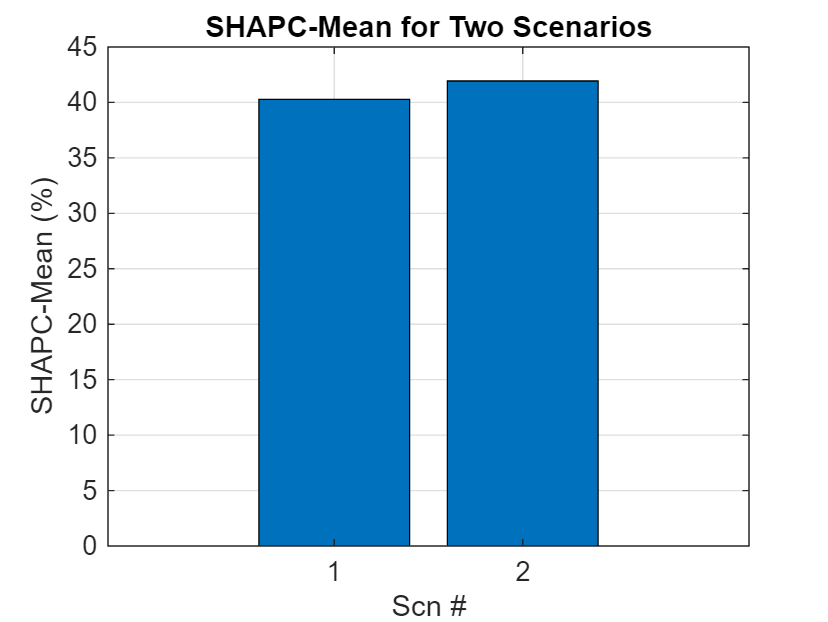

title('SHAPC-Mean for Two Scenarios');
xlabel('Scn #');
ylabel('SHAPC-Mean (%)');
grid on;